# **Tutorial - 2: Modeling an Electromagnet**

ELL851 - Computer Aided Design of Electrical Machines

**Problem Description: **

A ferromagnetic material, wound by a current carrying conductor, behaves as an electromagnet. 

What'll you understand: *Assigning material properties, winding assignment*

Reference Model for electromagnet: (consider copper wire gauge at 10 SWG, single conductor at 10A)

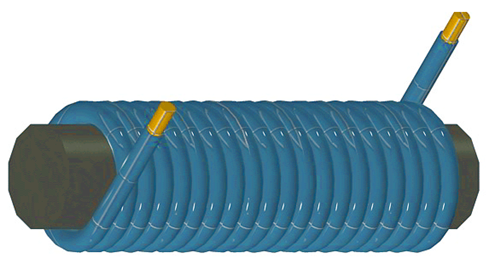 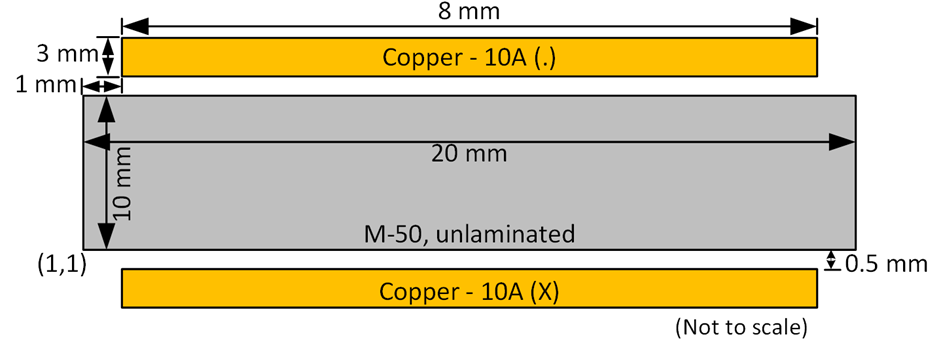

## Define Initial Design Parameters (Known)

clc; clear all;
freq  = 0; %frequency of the problem, Hz
CoreW = 20; CoreH = 10; %core width and core height, mm
CoilW = 8; CoilH = 3; %coil width and coil height, mm
gap = 0.5; %gap between core and coil
boundary_rad = 2.5*CoreW; % boundary radius, 2.5xCoreW

## Open FEMM and Define Initial Settings

openfemm(); newdocument(0); % for Magnetostatic problems
messagebox('Tutorial-II, Electromagnet'); %display name of tutorial
mi_probdef(freq,'millimeters','planar',1.e-8,0,30); %problem definition

## Geometry Definition

mi_drawrectangle ([-CoreW/2 0; CoreW/2 CoreH]) %Core
mi_drawrectangle ([-CoreW/2+1 CoreH + gap; CoreW/2-1 CoreH + gap + CoilH;])%top_Coil
mi_drawrectangle ([-CoreW/2+1 -gap; CoreW/2-1 -(gap + CoilH);])%bot_Coil
mi_drawarc(boundary_rad, CoreH/2, -boundary_rad, CoreH/2, 180, 5) %boundary arc 1
mi_drawarc(-boundary_rad, CoreH/2, boundary_rad, CoreH/2, 180, 5) %boundary arc 2
mi_zoomnatural

## Boundary Assignment

Use repeatable code sections wherever possible

mi_addboundprop('Air',0,0,0,0,0,0,0,0,0);
mi_selectarcsegment(0,boundary_rad); mi_selectarcsegment(0,-boundary_rad); %Select boundary 
mi_setarcsegmentprop(5, 'Air', 0, 1); %group 1
mi_clearselected

## Material Assignment

% Get materials and set materials to labels
mi_getmaterial('M-50'); mi_addblocklabel(0, CoreH/2); mi_selectlabel(0, CoreH/2);
mi_setblockprop('M-50',1,0,'None',0,1,0); %M-50, group 2
mi_clearselected();

mi_getmaterial('Air');mi_addblocklabel(0,boundary_rad/2); mi_selectlabel(0,boundary_rad/2);
mi_setblockprop('Air',1,0,'None',0,3,0); %Air, group 3
mi_clearselected();

turns = 1;
mi_getmaterial('10 SWG'); mi_addblocklabel(0,CoreH+gap+CoilH/2); 
mi_selectlabel(0,CoreH+gap+CoilH/2); mi_addcircprop('Winding', 10, 1);
mi_setblockprop('10 SWG',1,0,'Winding',0,0,turns); %Air, group 3
mi_clearselected();

mi_getmaterial('10 SWG'); mi_addblocklabel(0,-(gap+CoilH/2)); 
mi_selectlabel(0,-(gap+CoilH/2)); mi_addcircprop('Winding', 10, 1);
mi_setblockprop('10 SWG',1,0,'Winding',0,0,-turns); %Air, group 3
mi_clearselected();

## Analyze 

%Save before analyzing
mi_saveas('Assignment2.FEM'); mi_createmesh; mi_analyze;

Error using callfemm (line 11)
FEMM returns:
error: No current magnetics input in focus
stack traceback:
   1:  function `mi_saveas' [C]
   2:  main of string "lua2matlab(mi_saveas("Assignment2.FEM"))" at line 1


Error in mi_saveas (line 4)
callfemm(['mi_saveas(' , quote(fn) , ')' ]);

mi_loadsolution; mi_zoomnatural;
mo_showdensityplot(1,0,0.1,0.0,'bmag'); %outputs flux density 
mo_setgrid(0.5, 'cart');

# **Assignment 2 - Questions:**

1. Plot $B_x$ and $B_y$ at the contours shown in Fig. along '*A*' and '*C*' (contours in a single plot), '*B*' and '*D*' (contours in a single plot). 

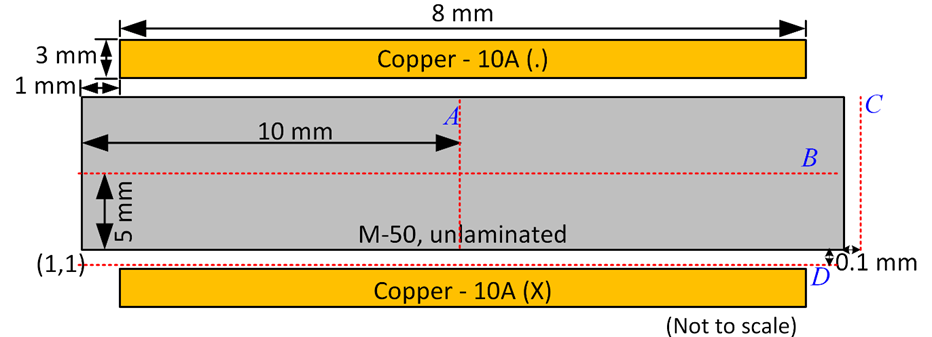

2. Vary the current (2.5A, 5A, 10A…) and the number of turns (10, 50, 100, 200…) and plot $B_x$*@C* vs current & $B_x$*@C* vs turns. Explain your findings.

(Additional work: ***Try testing out an axisymmetric solution for the same problem !***)